# Creating a sample undirected graph

clc;
clear all;
close all;
figure;
s = [1 1 2 2 3 3 4 4 4 5 6 7];
t = [2 3 4 6 4 5 5 7 6 8 7 8];
G = graph(s,t);
h = plot(G)

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {}
         XData: [-1.7426 -0.3553 -1.2459 0.0872 -0.2216 0.9435 1.4002 1.1347]
         YData: [-1.1347 -1.4002 0.2216 -0.0872 1.2459 -0.9435 0.3553 1.7426]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


h.XData = [-2 -0.5 -1   0 1  1.5 2   2.5];
h.YData = [ 0 -2    2.5 0 3 -2   0.3 1.5];
G.Nodes.NodeColors = [6; 1; 1; 1; 6; 1; 1; 1];
G.Edges.EdgeColors = [1; 1; 5; 1; 1; 1; 1; 1; 1; 1; 5; 1];
h.NodeCData = G.Nodes.NodeColors;
h.EdgeCData = G.Edges.EdgeColors;
h.EdgeLabel = [2.3, 2, 3, 1.5, 3.2, 2.2, 3.8, 2.6, 2.2, 2.8, 1.8, 0.8]

h =   GraphPlot with properties:

     NodeColor: 'flat'
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: 'flat'
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {'2.3'  '2'  '3'  '1.5'  '3.2'  '2.2'  '3.8'  '2.6'  '2.2'  '2.8'  '1.8'  '0.8'}
         XData: [-2 -0.5000 -1 0 1 1.5000 2 2.5000]
         YData: [0 -2 2.5000 0 3 -2 0.3000 1.5000]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


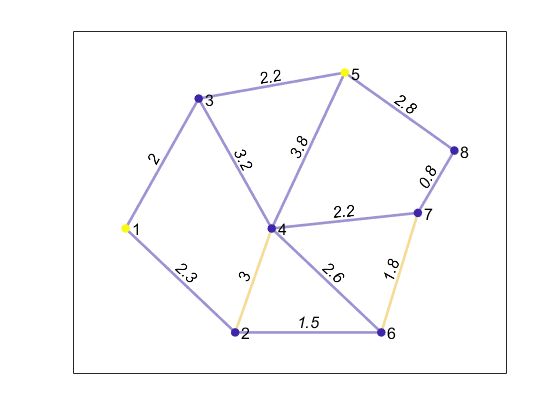

h.MarkerSize = 5.5;
h.LineWidth = 2;
h.NodeFontSize = 12;
h.EdgeFontSize = 12;

## Initializing Parameters


numNodes = 8;
numEdges = 12;
vehicleCapacity = 14;
graphMatrix = [  0 2.3 2 0 0   0 0 0;
               2.3   0 0 3 0 1.5 0 0;
                 2   0 0 3.2 2.2 0 0 0;
                 0 3 3.2 0 3.8 2.6 2.2 0;
                 0 0 2.2 3.8 0 0 0 2.8;
                 0 1.5 0 2.6 0 0 1.8 0;
                 0 0 0 2.2 0 1.8 0 0.8;
                 0 0 0 0 2.8 0 0.8 0];

requiredNodes = [2 4; 6 7];
uavsInDepotNodes = [0 2];
totalUavs = sum(uavsInDepotNodes);

totalUavs = 2

numrequiredEdges = 2;
depotNodes = [1 5];
arcTraversed = false;
visitedNodes = [];
taskAllocatedtoBaseStations = [];
exploredNodes.nodes = [];
allExploredNodes = repmat(exploredNodes, numNodes,1);
path.Tour = [];
path.Cost = [];
bestPath = repmat(path,numel(depotNodes),1);

## Task Allocation: Determining which acrs should be traversed by which base station.

depotNodesCost = zeros(numrequiredEdges, numel(depotNodes));
for i=1:numel(depotNodes)
    index = depotNodes(i);
    for j=1:numrequiredEdges
        arcTraversed = false;
        distance = 0;
        visitedNodes = [];
        while ~arcTraversed
            minCost = 0;
            for k=1:numNodes
                if graphMatrix(index,k) ~= 0 && ~ismember(k,visitedNodes)
                    if k == requiredNodes(j,1) || k == requiredNodes(j,2)
                        depotNodesCost(i,j) = distance + graphMatrix(index,k) + graphMatrix(requiredNodes(j,1), requiredNodes(j,2));
                        arcTraversed = true;
                        if numel(visitedNodes) == 0
                            if k == requiredNodes(j,1)
                                visitedNodes = [index k requiredNodes(j,2)];
                            else
                                visitedNodes = [index k requiredNodes(j,1)];
                            end
                        else
                           if k == requiredNodes(j,1)
                                visitedNodes = [visitedNodes k requiredNodes(j,2)];
                            else
                                visitedNodes = [visitedNodes k requiredNodes(j,1)];
                            end 
                        end
%                         visitedNodes
                        break;
                    else
                        if minCost == 0
                            minCost = graphMatrix(index,k) + min(abs(requiredNodes(j,1) - k), abs(requiredNodes(j,2) - k));                            
                            tempIndex = k;
                            if numel(visitedNodes) == 0
                                visitedNodes = [index];
                            end
%                             visitedNodes = [index]; 
                        else
                            if graphMatrix(index,k) + min(abs(requiredNodes(j,1) - k), abs(requiredNodes(j,2) - k)) < minCost
                                minCost = graphMatrix(index,k); %+  + min(abs(requiredNodes(j,1) - k), abs(requiredNodes(j,2) - k));                               
                                tempIndex = k;
                            end
                        end
                    end
                end
            end          
            if ~arcTraversed
                index = tempIndex;
                visitedNodes = [visitedNodes tempIndex];                  
            end
            distance = distance + minCost;
        end
    end
end


depotNodesCost =     5.3000    9.6000
    6.8000    5.4000


for i=1:numel(uavsInDepotNodes)
    if uavsInDepotNodes(i) == 0
        depotNodesCost(i,:) = inf;
    end
end

for i=1:numel(depotNodes)
    disp(['Allocating arc ' num2str(requiredNodes(i,1)) ' - ' num2str(requiredNodes(i,2)) ' to base station ' num2str(i) ' - node ' num2str(depotNodes(find(depotNodesCost(:,i) == min(depotNodesCost(:,i)))))])
    taskAllocatedtoBaseStations = [taskAllocatedtoBaseStations depotNodes(find(depotNodesCost(:,i) == min(depotNodesCost(:,i))))];
end

Allocating arc 2 - 4 to base station 1 - node 5
Allocating arc 6 - 7 to base station 2 - node 5


taskAllocatedtoBaseStations =      5     5


% Task Allocation Visualization - Part 1
clc;
clear all;
close all;
figure;
s = [1 1 2 2 3 3 4 4 4 5 6 7];
t = [2 3 4 6 4 5 5 7 6 8 7 8];
G = graph(s,t);
h = plot(G)
h.XData = [-2 -0.5 -1   0 1  1.5 2   2.5];
h.YData = [ 0 -2    2.5 0 3 -2   0.3 1.5];
G.Nodes.NodeColors = [6; 1; 1; 1; 6; 1; 1; 1];
G.Edges.EdgeColors = [1; 1; 5; 1; 1; 1; 1; 1; 1; 1; 5; 1];
h.NodeCData = G.Nodes.NodeColors;
h.EdgeCData = G.Edges.EdgeColors;
h.EdgeLabel = [2.3, 2, 3, 1.5, 3.2, 2.2, 3.8, 2.6, 2.2, 2.8, 1.8, 0.8]
h.MarkerSize = 5.5;
h.LineWidth = 2;
h.NodeFontSize = 12;
h.EdgeFontSize = 12;

hold on
s1 = [4,5]
t1 = [2,4]
G1 = digraph(s1, t1);
h1 = plot(G1,'Layout','force')
h1.XData = [-2 -0.5 -1  0 1];
h1.YData = [ 0 -2 2.5  0 3];
G1.Nodes.NodeColors = [6; 1; 1; 1; 6];
G1.Edges.EdgeColors = [10; 10];
h1.NodeCData = G1.Nodes.NodeColors;
h1.EdgeCData = G1.Edges.EdgeColors;
h1.EdgeLabel = [3, 3.8];
h1.MarkerSize = 5.5;
h1.LineWidth = 2;
h1.NodeFontSize = 12;
h1.EdgeFontSize = 12;
h1.ArrowSize = 16;

% Task Allocation Visualization - Part 2
clc;
clear all;
close all;
figure;
s = [1 1 2 2 3 3 4 4 4 5 6 7];
t = [2 3 4 6 4 5 5 7 6 8 7 8];
G = graph(s,t);
h = plot(G)
h.XData = [-2 -0.5 -1   0 1  1.5 2   2.5];
h.YData = [ 0 -2    2.5 0 3 -2   0.3 1.5];
G.Nodes.NodeColors = [6; 1; 1; 1; 6; 1; 1; 1];
G.Edges.EdgeColors = [1; 1; 5; 1; 1; 1; 1; 1; 1; 1; 5; 1];
h.NodeCData = G.Nodes.NodeColors;
h.EdgeCData = G.Edges.EdgeColors;
h.EdgeLabel = [2.3, 2, 3, 1.5, 3.2, 2.2, 3.8, 2.6, 2.2, 2.8, 1.8, 0.8]
h.MarkerSize = 5.5;
h.LineWidth = 2;
h.NodeFontSize = 12;
h.EdgeFontSize = 12;

hold on
s2 = [5,7,8]
t2 = [8,6,7]
G2 = digraph(s2, t2);
h2 = plot(G2,'Layout','force')
h2.XData = [-2 -0.5 -1   0 1  1.5 2   2.5];
h2.YData = [ 0 -2    2.5 0 3 -2   0.3 1.5];
G2.Nodes.NodeColors = [6; 1; 1; 1; 6; 1; 1; 1];
G2.Edges.EdgeColors = [3; 3; 3];
h2.NodeCData = G2.Nodes.NodeColors;
h2.EdgeCData = G2.Edges.EdgeColors;
h2.EdgeLabel = [2.8, 1.8, 0.8];
h2.MarkerSize = 5.5;
h2.LineWidth = 2;
h2.NodeFontSize = 12;
h2.EdgeFontSize = 12;
h2.ArrowSize = 16;
xlim([-2.3 3.2])
ylim([-2.80 3.80])

## Path Scanning Algorithm

% Constructing feasible cycles one at a time considering the following
% optimization conditions:
% 1. Decreasing the cost taken to travel from the base station to desired
% arc.
% 2. Decreasing the cost taken to travel from the desired arc back to base
% station.

for i=1:numel(depotNodes)
    index = taskAllocatedtoBaseStations(i)
    while true
        arcTraversed = false;
        cycleFormed = false;
        distance = 0;
        visitedNodes = [];
        while ~(arcTraversed && cycleFormed)
            minCost = 0;            
            for k=1:numNodes                
                if graphMatrix(index,k) ~= 0 && ~ismember(k,visitedNodes)
                    if ~arcTraversed
                        if k == requiredNodes(i,1) || k == requiredNodes(i,2)                                                       
                            bestPath(i).Cost = distance + graphMatrix(index,k) + graphMatrix(requiredNodes(i,1), requiredNodes(i,2));
                            arcTraversed = true;
                            if numel(visitedNodes) == 0
                                if k == requiredNodes(i,1)
                                    visitedNodes = [k requiredNodes(i,2)];                                  
                                else
                                    visitedNodes = [k requiredNodes(i,1)];
                                end
                            else
                               if k == requiredNodes(i,1)
                                    visitedNodes = [visitedNodes k requiredNodes(i,2)];                                 
                                   
                                else
                                    visitedNodes = [visitedNodes k requiredNodes(i,1)];
                               end 
                            end
                            tempIndex = visitedNodes(end);
                            index = tempIndex;
                            bestPath(i).Tour = visitedNodes;                            
                            visitedNodes = [];
                            distance = 0;
                            minCost = 0;
                        else
                            if minCost == 0                                                                
                                sum(ismember(allExploredNodes(index).nodes,k))
                                if sum(ismember(allExploredNodes(index).nodes,k)) == 0
                                    minCost = graphMatrix(index,k)                            
                                    tempIndex = k;
                                    if numel(visitedNodes) == 0
                                        visitedNodes = [index];
                                    end
                                end                   
                            else
                                if graphMatrix(index,k) < minCost && sum(ismember(allExploredNodes(index).nodes,k)) == 0
                                    minCost = graphMatrix(index,k);                               
                                    tempIndex = k;
                                end
                            end
                        end                     
                    else                        
                        for m=1:numNodes
                            if graphMatrix(index,m) ~= 0 && numel(find(ismember(depotNodes,m)==1)) ~= 0                                
                                bestPath(i).Cost = bestPath(i).Cost + distance + graphMatrix(index,m);
                                cycleFormed = true;
                                visitedNodes = [visitedNodes m];                                
                                bestPath(i).Tour = [bestPath(i).Tour visitedNodes];
                                break;
                            end
                        end
                        if ~cycleFormed                            
                            if minCost == 0                                
                                if sum(ismember(allExploredNodes(index).nodes,k)) == 0
                                    minCost = graphMatrix(index,k)                            
                                    tempIndex = k;      
                                end                   
                            else
                                if graphMatrix(index,k) < minCost && sum(ismember(allExploredNodes(index).nodes,k)) == 0
                                    minCost = graphMatrix(index,k); %+  + min(abs(requiredNodes(j,1) - k), abs(requiredNodes(j,2) - k));                               
                                    tempIndex = k;
                                end
                            end                            
                        else
                            break;
                        end              
                                                           
                    end
                end               
            end          
            if ~cycleFormed
                index = tempIndex;
                visitedNodes = [visitedNodes tempIndex];          
            end            
        end       
        if bestPath(i).Cost <= vehicleCapacity
            break;
        else
            allExploredNodes(bestPath(i).Tour(1)).nodes = [allExploredNodes(bestPath(i).Tour(1)).nodes bestPath(i).Tour(2)]
            bestPath(i).Cost = [];
            bestPath(i).Tour = [];
            index = taskAllocatedtoBaseStations(i);
        end
    end
end

index = 5

index = 5

k = 3

ans = 0

minCost = 2.2000

index = 5

tempIndex = 3

k = 3

distance = 0

minCost = 2.2000

\n


Eashwar1


k = 4

bestPath = 2×1 struct array with fields:
    Tour
    Cost


bestPath = 2×1 struct array with fields:
    Tour
    Cost


index = 2

tempIndex = 2

k = 4

distance = 0

minCost = 0

\n


index = 2


visitedNodes =

     []



Eashwar4


index = 2

m = 1

distance = 0

ans = 2.3000

visitedNodes = 1

bestPath = 2×1 struct array with fields:
    Tour
    Cost


distance = 0

minCost = 0

distance = 0

bestPath = 2×1 struct array with fields:
    Tour
    Cost


index = 5

index = 5

k = 3

ans = 0

minCost = 2.2000

index = 5

tempIndex = 3

k = 3

distance = 0

minCost = 2.2000

\n


index = 5

tempIndex = 3

k = 4

distance = 0

minCost = 2.2000

\n


index = 5

tempIndex = 3

k = 8

distance = 0

minCost = 2.2000

\n


distance = 0

minCost = 2.2000

distance = 2.2000

index = 3

k = 1

ans = 0

minCost = 2

index = 3

tempIndex = 1

k = 1

distance = 2.2000

minCost = 2

\n


index = 3

tempIndex = 1

k = 4

distance = 2.2000

minCost = 2

\n


distance = 2.2000

minCost = 2

distance = 4.2000

index = 1

k = 2

ans = 0

minCost = 2.3000

index = 1

tempIndex = 2

k = 2

distance = 4.2000

minCost = 2.3000

\n


distance = 4.2000

minCost = 2.3000

distance = 6.5000

index = 2

k = 4

ans = 0

minCost = 3

index = 2

tempIndex = 4

k = 4

distance = 6.5000

minCost = 3

\n


Eashwar1


k = 6

bestPath = 2×1 struct array with fields:
    Tour
    Cost


bestPath = 2×1 struct array with fields:
    Tour
    Cost


index = 7

tempIndex = 7

k = 6

distance = 0

minCost = 0

\n


index = 7


visitedNodes =

     []



Eashwar3


minCost = 0

index = 7

k = 8


ans =

     []



k = 8

ans = 0

minCost = 0.8000

minCost = 0.8000

index = 7

k = 8

distance = 0

minCost = 0.8000

distance = 0.8000

index = 8

visitedNodes = 8

Eashwar4


index = 8

m = 5

distance = 0.8000

ans = 2.8000

visitedNodes =      8     5


bestPath = 2×1 struct array with fields:
    Tour
    Cost


distance = 0.8000

minCost = 0

distance = 0.8000

bestPath = 2×1 struct array with fields:
    Tour
    Cost


allExploredNodes = 8×1 struct array with fields:
    nodes


index = 5

index = 5

k = 3

ans = 1

index = 5

tempIndex = 8

k = 3

distance = 0

minCost = 0

\n


index = 5

k = 4

ans = 0

minCost = 3.8000

index = 5

tempIndex = 4

k = 4

distance = 0

minCost = 3.8000

\n


index = 5

tempIndex = 8

k = 8

distance = 0

minCost = 2.8000

\n


distance = 0

minCost = 2.8000

distance = 2.8000

Eashwar1


k = 7

bestPath = 2×1 struct array with fields:
    Tour
    Cost


bestPath = 2×1 struct array with fields:
    Tour
    Cost


index = 6

tempIndex = 6

k = 7

distance = 0

minCost = 0

\n


distance = 0

minCost = 0

distance = 0

index = 6

visitedNodes = 6

Eashwar3


minCost = 0

index = 6

k = 2


ans =

     []



k = 2

ans = 0

minCost = 1.5000

minCost = 1.5000

index = 6

k = 2

index = 6

visitedNodes = 6

Eashwar3


minCost = 1.5000

index = 6

k = 4

minCost = 1.5000

index = 6

k = 4

index = 6

visitedNodes = 6

Eashwar3


minCost = 1.5000

index = 6

k = 7

minCost = 1.5000

index = 6

k = 7

distance = 0

minCost = 1.5000

distance = 1.5000

index = 2

visitedNodes =      6     2


Eashwar4


index = 2

m = 1

distance = 1.5000

ans = 2.3000

visitedNodes =      6     2     1


bestPath = 2×1 struct array with fields:
    Tour
    Cost


distance = 1.5000

minCost = 0

distance = 1.5000

bestPath = 2×1 struct array with fields:
    Tour
    Cost


%Adding depot nodes to the solution path and removing redundant nodes from the
%solution path
for i=1:numel(depotNodes)
    temp = [];
    numel(bestPath(i).Tour)
    if depotNodes(i) ~= bestPath(i).Tour(1)
       bestPath(i).Tour = [depotNodes(i) bestPath(i).Tour];
    end    
    for j=1:numel(bestPath(i).Tour)-1           
       if bestPath(i).Tour(j) ~= bestPath(i).Tour(j+1)
           if j == numel(bestPath(i).Tour)-1
               temp = [temp bestPath(i).Tour(j) bestPath(i).Tour(j+1)];           
           else
               temp = [temp bestPath(i).Tour(j)];
           end           
       end       
    end
    bestPath(i).Tour = temp;
end

% Path 1 Visualization
clc;
clear all;
close all;
figure;
s = [1 1 2 2 3 3 4 4 4 5 6 7];
t = [2 3 4 6 4 5 5 7 6 8 7 8];
G = graph(s,t);
h = plot(G)

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {}
         XData: [-1.7426 -0.3553 -1.2459 0.0872 -0.2216 0.9435 1.4002 1.1347]
         YData: [-1.1347 -1.4002 0.2216 -0.0872 1.2459 -0.9435 0.3553 1.7426]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


h.XData = [-2 -0.5 -1   0 1  1.5 2   2.5];
h.YData = [ 0 -2    2.5 0 3 -2   0.3 1.5];
G.Nodes.NodeColors = [6; 1; 1; 1; 6; 1; 1; 1];
G.Edges.EdgeColors = [1; 1; 5; 1; 1; 1; 1; 1; 1; 1; 5; 1];
h.NodeCData = G.Nodes.NodeColors;
h.EdgeCData = G.Edges.EdgeColors;
h.EdgeLabel = [2.3, 2, 3, 1.5, 3.2, 2.2, 3.8, 2.6, 2.2, 2.8, 1.8, 0.8]

h =   GraphPlot with properties:

     NodeColor: 'flat'
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: 'flat'
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {'2.3'  '2'  '3'  '1.5'  '3.2'  '2.2'  '3.8'  '2.6'  '2.2'  '2.8'  '1.8'  '0.8'}
         XData: [-2 -0.5000 -1 0 1 1.5000 2 2.5000]
         YData: [0 -2 2.5000 0 3 -2 0.3000 1.5000]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


h.MarkerSize = 5.5;
h.LineWidth = 2;
h.NodeFontSize = 12;
h.EdgeFontSize = 12;

hold on
s1 = [2,4,5]

s1 =      2     4     5


t1 = [1,2,4]

t1 =      1     2     4


G1 = digraph(s1, t1);
h1 = plot(G1,'Layout','force')

h1 =   GraphPlot with properties:

     NodeColor: [0.8500 0.3250 0.0980]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0.8500 0.3250 0.0980]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'}
     EdgeLabel: {}
         XData: [2.2546 1.6235 2.8427 0.9252 0.2941]
         YData: [0.2941 0.9252 0.2941 1.6235 2.2546]
         ZData: [0 0 0 0 0]

  Show all properties


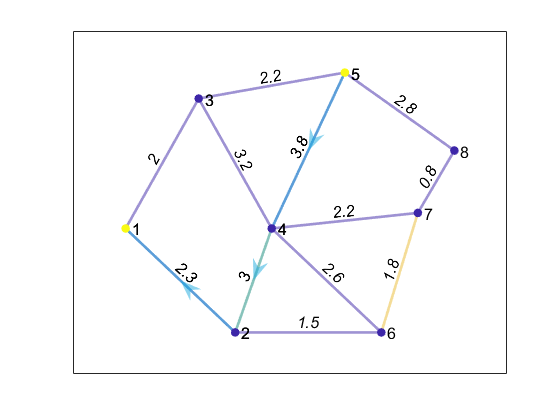

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {}
         XData: [-1.7426 -0.3553 -1.2459 0.0872 -0.2216 0.9435 1.4002 1.1347]
         YData: [-1.1347 -1.4002 0.2216 -0.0872 1.2459 -0.9435 0.3553 1.7426]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


h =   GraphPlot with properties:

     NodeColor: 'flat'
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: 'flat'
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {'2.3'  '2'  '3'  '1.5'  '3.2'  '2.2'  '3.8'  '2.6'  '2.2'  '2.8'  '1.8'  '0.8'}
         XData: [-2 -0.5000 -1 0 1 1.5000 2 2.5000]
         YData: [0 -2 2.5000 0 3 -2 0.3000 1.5000]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


s1 =      4     5


t1 =      2     4


h1 =   GraphPlot with properties:

     NodeColor: [0.8500 0.3250 0.0980]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0.8500 0.3250 0.0980]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'}
     EdgeLabel: {}
         XData: [2.2528 1.7867 2.7189 1.0098 0.2330]
         YData: [0.2330 0.2330 0.2330 1.0099 1.7867]
         ZData: [0 0 0 0 0]

  Show all properties


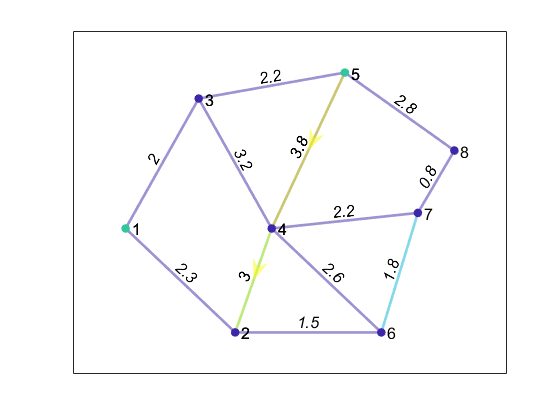

h1.XData = [-2 -0.5 -1  0 1];
h1.YData = [ 0 -2 2.5  0 3];
G1.Nodes.NodeColors = [6; 1; 1; 1; 6];
G1.Edges.EdgeColors = [3; 3; 3];
h1.NodeCData = G1.Nodes.NodeColors;
h1.EdgeCData = G1.Edges.EdgeColors;
h1.EdgeLabel = [2.3, 3, 3.8];
h1.MarkerSize = 5.5;
h1.LineWidth = 2;
h1.NodeFontSize = 12;
h1.EdgeFontSize = 12;
h1.ArrowSize = 16;

% Path 2 Visualization
clc;
clear all;
close all;
figure;
s = [1 1 2 2 3 3 4 4 4 5 6 7];
t = [2 3 4 6 4 5 5 7 6 8 7 8];
G = graph(s,t);
h = plot(G)

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {}
         XData: [-1.7426 -0.3553 -1.2459 0.0872 -0.2216 0.9435 1.4002 1.1347]
         YData: [-1.1347 -1.4002 0.2216 -0.0872 1.2459 -0.9435 0.3553 1.7426]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


h.XData = [-2 -0.5 -1   0 1  1.5 2   2.5];
h.YData = [ 0 -2    2.5 0 3 -2   0.3 1.5];
G.Nodes.NodeColors = [6; 1; 1; 1; 6; 1; 1; 1];
G.Edges.EdgeColors = [1; 1; 5; 1; 1; 1; 1; 1; 1; 1; 5; 1];
h.NodeCData = G.Nodes.NodeColors;
h.EdgeCData = G.Edges.EdgeColors;
h.EdgeLabel = [2.3, 2, 3, 1.5, 3.2, 2.2, 3.8, 2.6, 2.2, 2.8, 1.8, 0.8]

h =   GraphPlot with properties:

     NodeColor: 'flat'
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: 'flat'
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {'2.3'  '2'  '3'  '1.5'  '3.2'  '2.2'  '3.8'  '2.6'  '2.2'  '2.8'  '1.8'  '0.8'}
         XData: [-2 -0.5000 -1 0 1 1.5000 2 2.5000]
         YData: [0 -2 2.5000 0 3 -2 0.3000 1.5000]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


h.MarkerSize = 5.5;
h.LineWidth = 2;
h.NodeFontSize = 12;
h.EdgeFontSize = 12;

hold on
s2 = [2,5,6,7,8]

s2 =      2     5     6     7     8


t2 = [1,8,2,6,7]

t2 =      1     8     2     6     7


G2 = digraph(s2, t2);
h2 = plot(G2,'Layout','force')

h2 =   GraphPlot with properties:

     NodeColor: [0.8500 0.3250 0.0980]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0.8500 0.3250 0.0980]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {}
         XData: [0.3801 0.8380 3.6741 4.4343 2.9140 1.3705 1.9240 2.4558]
         YData: [2.9140 2.4561 0.3801 0.3801 0.3801 1.9236 1.3701 0.8383]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


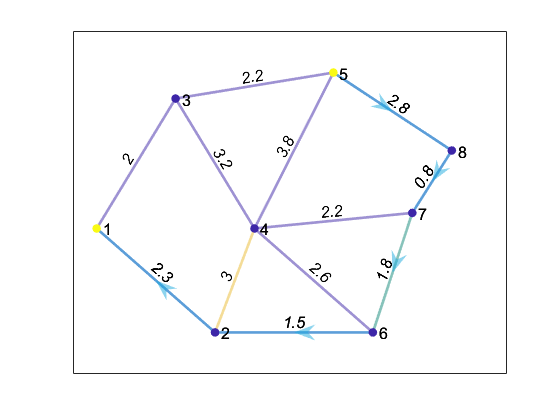

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {}
         XData: [-1.7426 -0.3553 -1.2459 0.0872 -0.2216 0.9435 1.4002 1.1347]
         YData: [-1.1347 -1.4002 0.2216 -0.0872 1.2459 -0.9435 0.3553 1.7426]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


h =   GraphPlot with properties:

     NodeColor: 'flat'
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: 'flat'
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {'2.3'  '2'  '3'  '1.5'  '3.2'  '2.2'  '3.8'  '2.6'  '2.2'  '2.8'  '1.8'  '0.8'}
         XData: [-2 -0.5000 -1 0 1 1.5000 2 2.5000]
         YData: [0 -2 2.5000 0 3 -2 0.3000 1.5000]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


s2 =      2     4     5     6     7     8


t2 =      1     2     8     4     6     7


h2 =   GraphPlot with properties:

     NodeColor: [0.8500 0.3250 0.0980]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0.8500 0.3250 0.0980]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'}
     EdgeLabel: {}
         XData: [0.3961 0.7818 3.8289 1.2376 3.0367 1.7182 2.1968 2.6506]
         YData: [3.2849 2.8701 0.4285 2.3783 0.4285 1.8586 1.3399 0.8478]
         ZData: [0 0 0 0 0 0 0 0]

  Show all properties


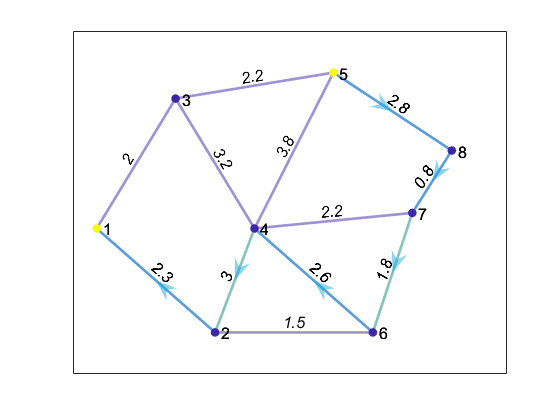

h2.XData = [-2 -0.5 -1   0 1  1.5 2   2.5];
h2.YData = [ 0 -2    2.5 0 3 -2   0.3 1.5];
G2.Nodes.NodeColors = [6; 1; 1; 1; 6; 1; 1; 1];
G2.Edges.EdgeColors = [3; 3; 3; 3; 3];
h2.NodeCData = G2.Nodes.NodeColors;
h2.EdgeCData = G2.Edges.EdgeColors;
h2.EdgeLabel = [2.3, 2.8, 1.5, 1.8, 0.8];
h2.MarkerSize = 5.5;
h2.LineWidth = 2;
h2.NodeFontSize = 12;
h2.EdgeFontSize = 12;
h2.ArrowSize = 16;
xlim([-2.3 3.2])
ylim([-2.80 3.80])